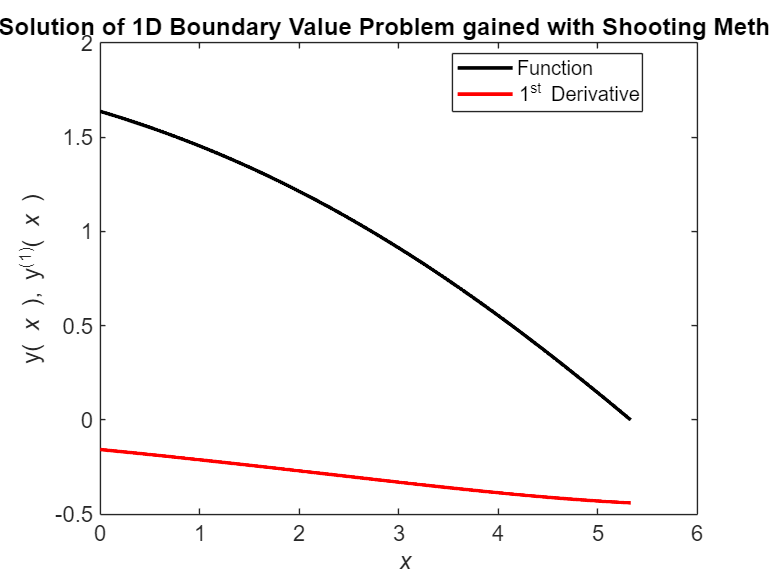

Elapsed time is 0.096655 seconds.


%This is a test file for beam bending simulation

clear, close all
%Knowns
EI = .37; %Random number for now



%Calculate curvature 

r = 5/3.14; %vine robot radius
n = 1; %Number of segments

% Actuator start positions (column vectors)
act_11_start = [r; 0; 0; 1];
act_12_start = [r*cos(2*pi/3); r*sin(2*pi/3); 0; 1];
act_13_start = [r*cos(4*pi/3); r*sin(4*pi/3); 0; 1];
Base_coord = eye(4);

[T,act1,act2,act3, curvature,Lck,beta,theta] = gen_transform_2(4,6,6,r,act_11_start,act_12_start,act_13_start,Base_coord);

R = 1/curvature;
%Set Fx and Fy

Fx = 0.01; %N
Fy = -0.02; 

%ignore gravity (q) for now

%Set ICs
%shooting_method_2

%Test shooting method for some arbitrary curve
[s_after,after] = shooting_method(@(x,y) eul_fun(x,y,EI,R,Fx,Fy),.005,1e-6,0,Lck,[-1/R 0],'df');

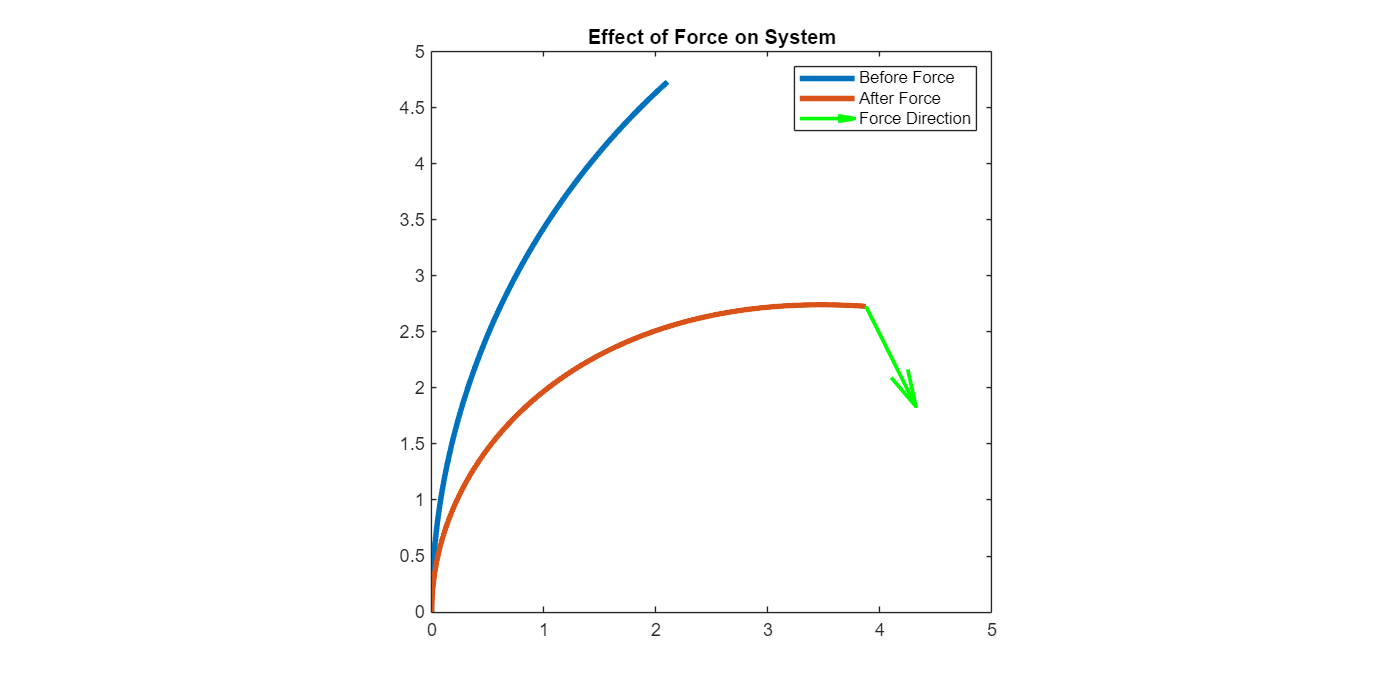


%This works, but I need to verify that it makes physical sense
%I want to graph the actual 2D curve and compare

%So, lets define the number of points

N = 100;

arc_val = linspace(0,Lck,N);

%Integrate 
%If straight, ignore
if curvature == 0
    y_before = arc_val;
    x_before = zeros(size(arc_val));
else
    theta_before = curvature*arc_val;
    y_before = 1/curvature*sin(theta_before);
    x_before = 1/curvature*(1-cos(theta_before));
end

    %Now do the same for the result
    %y1 is theta and y2 is thetadot

%Take derivative of arc length
d_arc = diff(s_after);
theta_after = flip(after(1,:));
theta_mid = theta_after(1:end-1) + diff(theta_after)/2;  % Midpoint approximation
y_after = [0, cumsum(d_arc .* cos(theta_mid))];
x_after =  [0, cumsum(d_arc .* sin(theta_mid))];


figure('Position',[10 10 1000 500])
plot(x_before, y_before, 'LineWidth', 3);
hold on
plot(x_after,y_after,'LineWidth',3);
axis equal;
ylim([0 5])
xlim([0 5])
quiver(x_after(end),y_after(end),Fx/sqrt(Fx^2+Fy^2),Fy/sqrt(Fx^2+Fy^2),'Color','green','LineWidth',2,'AutoScaleFactor',1,'MaxHeadSize',10)
legend('Before Force','After Force','Force Direction','Location','northeast')
title('Effect of Force on System')








function dy = eul_fun(x,y,EI,R,Fx,Fy)
    dy = zeros(1,2);
    dy(1) = y(2);
    dy(2) = 1/EI*(-Fx*cos(y(1))+Fy*sin(y(1)));
 end



function [T_k, act_1_end, act_2_end, act_3_end, rho_k,L_ck,beta_k,theta_k] = ...
    gen_transform_2(L_k1, L_k2, L_k3, r, act_1_start, act_2_start, act_3_start, T_prev)

    phi_kj = 0; % fixed angle

    % calculate length
    L_ck = (L_k1 + L_k2 + L_k3)/3;
    beta_k = 2*sqrt(L_k1^2 + L_k2^2 + L_k3^2 - L_k1*L_k2 - L_k1*L_k3 - L_k2*L_k3)/(3*r);
    theta_k = atan2(3*(L_k2 - L_k3), sqrt(3)*(L_k2 + L_k3 - 2*L_k1));

    rho_k = beta_k/L_ck; % Curvature calc

    % Rotation matrix
    ct = cos(theta_k);
    st = sin(theta_k);
    cb = cos(beta_k);
    sb = sin(beta_k);

    R_k = [
        cb*ct^2 + st^2,      (cb-1)*ct*st,       ct*sb;
        (cb-1)*ct*st,        ct^2 + cb*st^2,     st*sb;
        -ct*sb,              -st*sb,             cb
    ];

    % Position vector
    P_k = (1/rho_k) * [(1-cb)*ct; (1-cb)*st; sb];

    % Transformation matrix
    T_k = [R_k P_k; 0 0 0 1];
    if abs(rho_k) < 1e-6
        T_k = [1 0 0 0
               0 1 0 0
               0 0 1 L_ck
               0 0 0 1];
    end
    % actuator end point calculation
    act_1_end = T_prev*T_k*act_1_start;
    act_2_end = T_prev*T_k*act_2_start;
    act_3_end = T_prev*T_k*act_3_start;
end